load('betamodel.mat')
% dataname = "Run2\_0p5uA.dat";
% date = " 29 Jul 2017";
MCE(1)=ImportSR830MCE('TmAsO4-LS5341_4p5K_20Oeps_1uAKiethley_SR860_Puck666.dat',1e-6);

Error using textscan
Mismatch between file and format character vector.
Trouble reading 'Numeric' field from file (row number 12, field number 8) ==> Bridge 1 Excitation (uA),Bridge 2 Resistivity (Ohm-m),Bridge 2 Excitation (uA),Bridge 3 Resistivity (Ohm-m),Bridge 3 Excitation (uA),Bridge 4 Resistivity (Ohm-m),Bridge 4 Excitation (uA),Bridge 1 Std....

Error in ImportPPMSMCE (line 56)
dataArray = textscan(fileID, formatSpec, endRow(1)-startRow(1)+1, 'Delimiter', delimiter, 'EmptyValue' ,NaN,'HeaderLines', startRow(1)-

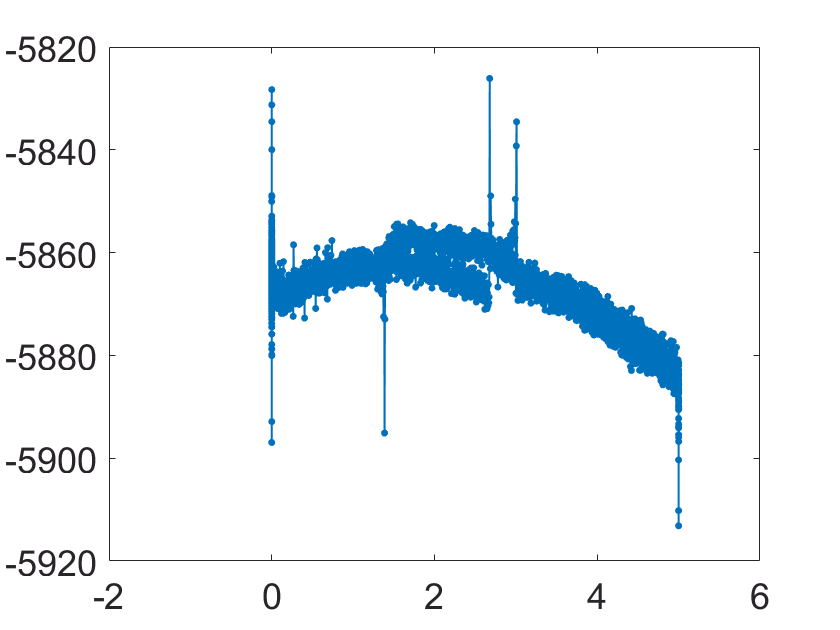

plot(MCE(1).H,MCE(1).ResPlat,'.-')

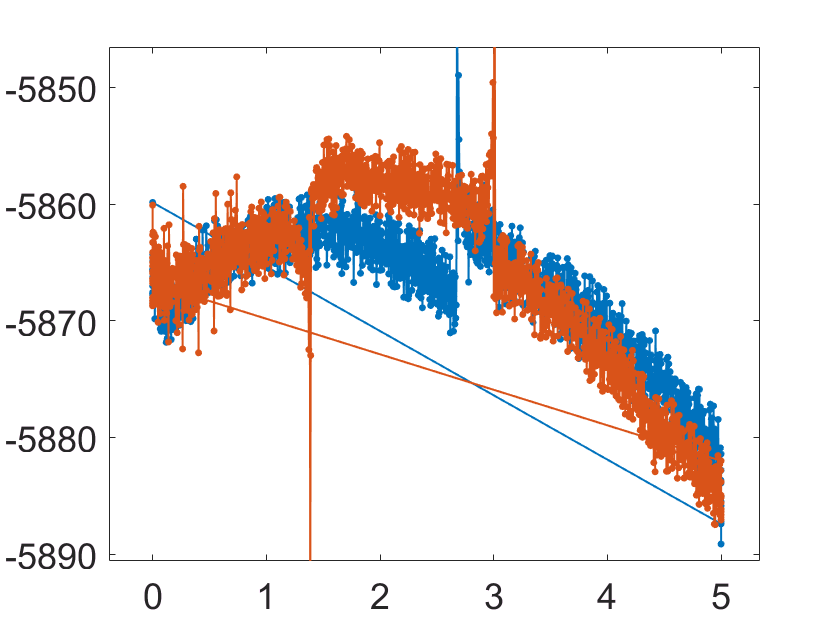

% ref_sweep = 0.6e-3;%Reference sweep rate of magnetic field (in Tesla/s) used 
%to discriminate between high and low sweep rates
FilterUp = diff(MCE(1).H)>0;
FilterDown = diff(MCE(1).H)<0;
Hup = MCE(1).H(FilterUp);
ResUp = MCE(1).ResPlat(FilterUp);
Hdown = MCE(1).H(FilterDown);
ResDown = MCE(1).ResPlat(FilterDown);
figure
plot(Hup,ResUp,'.-')
hold on
plot(Hdown,ResDown,'.-')

legend('Up','Down')

plot(SR830MCE(3).H,1./BetaModel(SR830MCE(3).H,SR830MCE(3).ResPlat))% R depends on T and H
% R and H are known in the experiment; we want to know T
% BetaModel results from the fit of 1/T as a function of R and H using the
% calibration file 'thermometer_calibration_raw.txt'
xlabel('Field (Oe)')
ylabel('Temperature (K)')
title('T-H MCE traces ')

sgm=10;%number of points for smoothing
newH=gConvolve(SR830MCE(3).H,sgm);%smooth the field data
newT=gConvolve(1./BetaModel(SR830MCE(3).H,SR830MCE(3).ResPlat),sgm);%smooth the temperature data
NewD=diff(newT);%compute the derivative of the smoothed temperature

figure
plot(newH(30:(end-30)),NewD(30:(end-29))*50+SR830MCE(3).TPuck(30:(end-30)),'-')%plot dT/dH versus H
%ylim([0.3 1.5])
xlabel('Field (Oe)')
ylabel('dT/dH + T_{puck}')
title('MCE effect')

figure;
yyaxis left;
plot(diff(SR830MCE(3).H),'DisplayName','Raw');
hold on;
plot(diff(newH),'-g','DisplayName','Smoothed');
xlabel('Measurement time t (s)')
ylabel('dH/dt (T/s)')
title('Sweep rate and puck temperature')
legend('show')

yyaxis right;
plot(SR830MCE(3).TPuck,'DisplayName','Puck temperature')
ylabel('T_{puck} (K)')

ref_sweep = 0.6e-3;%Reference sweep rate of magnetic field (in Tesla/s) used 
%to discriminate between high and low sweep rates
FilterFastUp = diff(newH)>ref_sweep;
FilterSlowUp = diff(newH)>0 &  diff(newH)<ref_sweep;
FilterFastDown = diff(newH)<-ref_sweep;
FilterSlowDown = diff(newH)<0 &  diff(newH)>-ref_sweep;

figure
SelectOnlyFastUp.newH=newH(FilterFastUp);
SelectOnlyFastUp.newH=SelectOnlyFastUp.newH(30:(end-30));
SelectOnlyFastUp.NewD=NewD(FilterFastUp);
SelectOnlyFastUp.NewD=SelectOnlyFastUp.NewD(30:(end-30));
SelectOnlyFastUp.TPuck=SR830MCE(3).TPuck(FilterFastUp);
SelectOnlyFastUp.TPuck=SelectOnlyFastUp.TPuck(30:(end-30));
plot(SelectOnlyFastUp.newH,SelectOnlyFastUp.NewD*50+SelectOnlyFastUp.TPuck,'.')
xlabel('Field(Oe)')
ylabel('He3 Temperature + dT_{Platform}/dH')
maintitle = dataname + date + newline;
title(maintitle + "Sweeping up in field at 8 Oe/s (0.4K) and 10 Oe/s (1.0K, 1.1K, 1.2K, 1.3K)")

figure
SelectOnlySlowUp.newH=newH(FilterSlowUp);
SelectOnlySlowUp.NewD=NewD(FilterSlowUp);
SelectOnlySlowUp.TPuck=SR830MCE(3).TPuck(FilterSlowUp);
%pts_ctff = 50;%Number of points to cut off when plotting the data in order 
%to avoid the Gaussian aberrations at the edges of the plots
%SelectOnlySlowUp.newH=SelectOnlySlowUp.newH(pts_ctff:(end-pts_ctff));
%SelectOnlySlowUp.NewD=SelectOnlySlowUp.NewD(pts_ctff:(end-pts_ctff));
%SelectOnlySlowUp.TPuck=SelectOnlySlowUp.TPuck(pts_ctff:(end-pts_ctff));
plot(SelectOnlySlowUp.newH,SelectOnlySlowUp.NewD*100+SelectOnlySlowUp.TPuck,'.')
xlabel('Field(Oe)')
ylabel('He3 Temperature + dT_{Platform}/dH*100')
title(maintitle + "Sweeping up in field at 4 Oe/s")

figure
SelectOnlyFastDown.newH=newH(FilterFastDown);
SelectOnlyFastDown.NewD=NewD(FilterFastDown);
SelectOnlyFastDown.TPuck=SR830MCE(3).TPuck(FilterFastDown);
plot(SelectOnlyFastDown.newH,SelectOnlyFastDown.NewD*50+SelectOnlyFastDown.TPuck,'.')
xlabel('Field(Oe)')
ylabel('He3 Temperature + dT_{Platform}/dH')
title(maintitle + "Sweeping down in field at 8 Oe/s (0.4K) and 10 Oe/s (1.0K, 1.1K, 1.2K, 1.3K)")

figure
SelectOnlySlowDown.newH=newH(FilterSlowDown);
SelectOnlySlowDown.NewD=NewD(FilterSlowDown);
SelectOnlySlowDown.TPuck=SR830MCE(3).TPuck(FilterSlowDown);
plot(SelectOnlySlowDown.newH,SelectOnlySlowDown.NewD*100+SelectOnlySlowDown.TPuck,'.')
xlabel('Field(Oe)')
ylabel('He3 Temperature + dT_{Platform}/dH')
title(maintitle + "Sweeping down in field at 4 Oe/s")

figure
plot(SelectOnlyFastDown.newH,SelectOnlyFastDown.NewD*50+SelectOnlyFastDown.TPuck,'.','DisplayName','10 Oe/s down')
hold on
plot(SelectOnlySlowDown.newH,SelectOnlySlowDown.NewD*100+SelectOnlySlowDown.TPuck,'.','DisplayName','4 Oe/s down')
plot(SelectOnlySlowUp.newH,SelectOnlySlowUp.NewD*100+SelectOnlySlowUp.TPuck,'.','DisplayName','4 Oe/s up')

plot(SelectOnlyFastUp.newH,SelectOnlyFastUp.NewD*50+SelectOnlyFastUp.TPuck,'.','DisplayName','10 Oe/s up')
xlabel('Field(Oe)')
ylabel('He3 Temperature + dT_{Platform}/dH')
title(maintitle + "Comparing sweep rates")
legend('show')